# Random Signals

## **Probability models and random variables**  

A signal is ***random*** if we cannot predict exactly its future values from its past values. A *deterministic *signal can be predicted exactly from its past values.  

An experiment whose outcome cannot be predicted with certainty is called a ***random experiment***.

The outcome of a random experiment is denoted $\zeta \in S$ (Greek letter zeta). The collection of all possible outcomes, called the ***sample space*** $S$. For example, if a die has 6 sides then the sample space is $S=\left\lbrace 1,2,3,4,5,6\right\rbrace$. The figure below shows the results of 1000 throws of six-sided die:

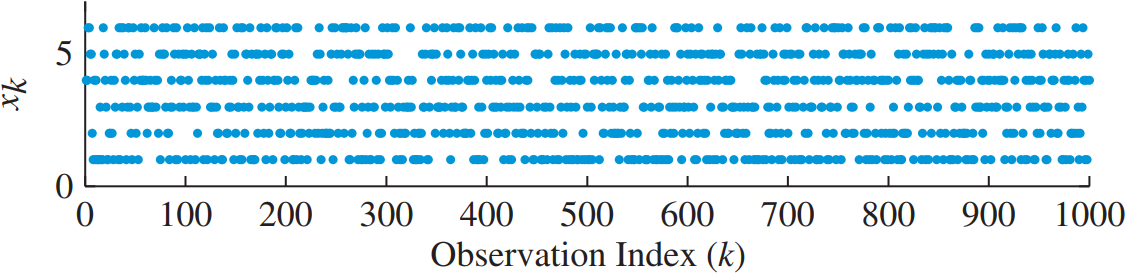

A subset of the sample space $S$ is called an **event**. For example, the event ($X<4$) is the subset of $\left\lbrace 1,2,3\right\rbrace$ of $S$.

The ***relative frequency*** of an event $A$ $f_N \left(A\right)$ is given by the number of occurrences of the event $A$ divided by the total number of trails:


$$f_N \left(A\right)=\frac{N\left(A\right)}{N}=\frac{\mathrm{Number}\;\mathrm{of}\;\mathrm{occurrences}\;\mathrm{of}\;\mathrm{event}\;A}{\mathrm{Total}\;\mathrm{number}\;\mathrm{of}\;\mathrm{trails}}$$


Example:

The number of occurrences of the event $\left(X<4\right)$ is $N\left(X<4\right)=6$. The relative frequency $f_{10} \left(X<4\right)=0\ldotp 6$.

## Random variables

A random variable is a variable that can take on a numerical value determined by the outcome of a random experiment.

A random variable is defined on a sample space $S$. 

A random variable $X\left(\zeta \right)$ is a function that assigns a real number to any outcome $\zeta$ i.e. $X : S \to \mathbb{R}$. For simplicity, we often drop the dependence on the outcome and write $X$.

We use capital letters to denote random variables and lower-case letters for values they may take. For example, $X=x$ means that $X$ takes on the value $x$.  

A ***discrete ***random variable can take values from a finite or countably infinite set of numbers.

A ***continuous*** random variable can take values from any real number in a specified range.

### Probability

If the number of trails $N$ is small, then the relative frequency of an event tend to be very unstable.

Empirical evidence show that the relative frequency of an event  stabilises around some number  as  goes towards infinity. This number  is between zero and one is called the ***probability*** of the event $A$.

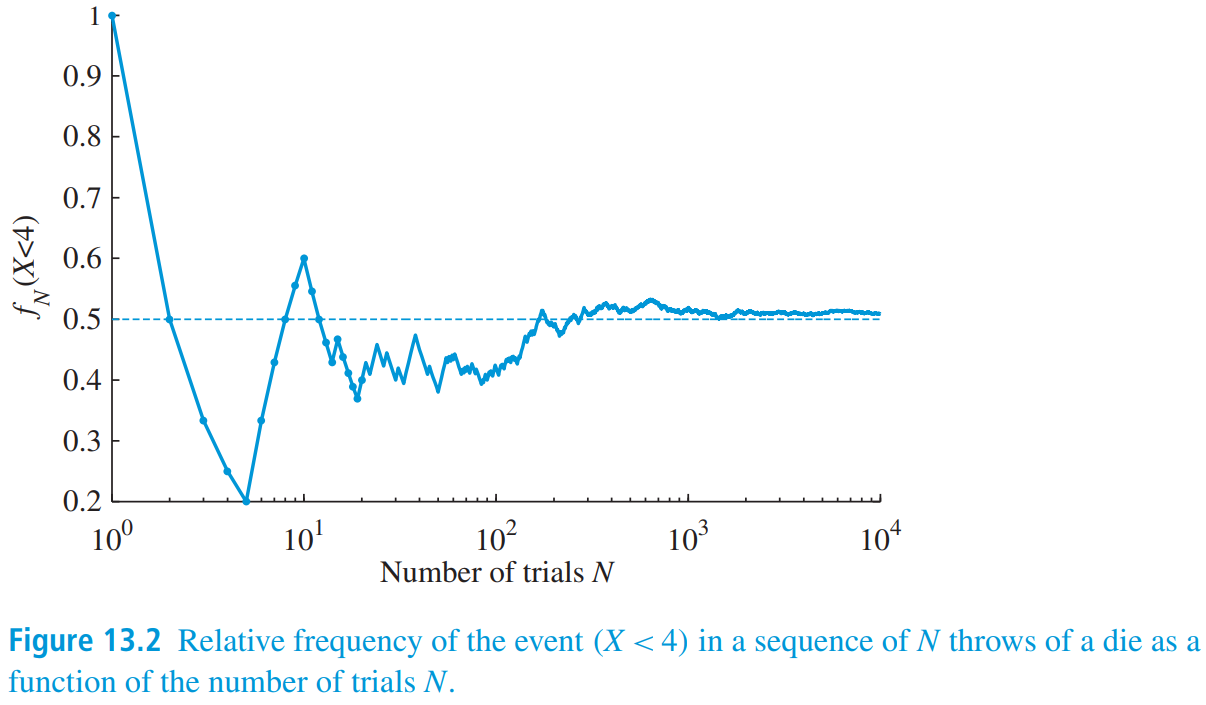

A random variable is described by specifying all the values that it can take together with their associated probabilities.

For discrete random variables with a finite number $M$ of possible values, this is done by 


$$\left\lbrace \left(x_1 ,P\left(x_1 \right)\right),\left(x_2 ,P\left(x_2 \right),\cdots ,\left(x_M ,P\left(x_M \right)\right)\right)\right\rbrace$$


For continuous random values, the probability of picking any specific number is zero. Probabilities are assigned to intervals, which is represented as areas over those intervals.

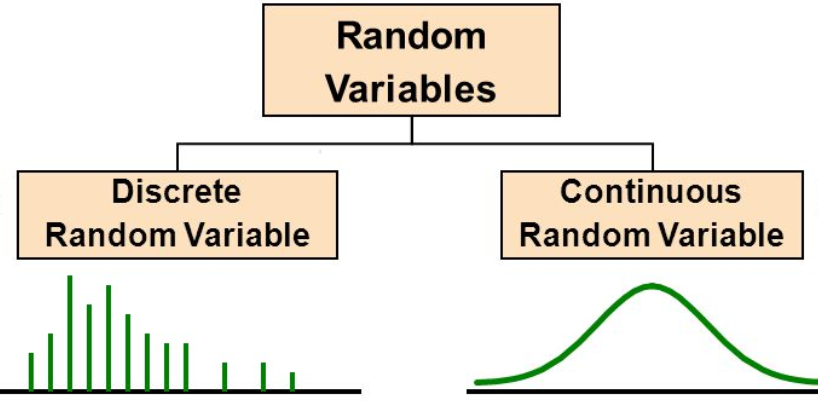

### Probability distributions

We can study the nature of a random variable by its probability distribution.

A probability distribution can constructed by creating a *histogram *of a large set of observations.

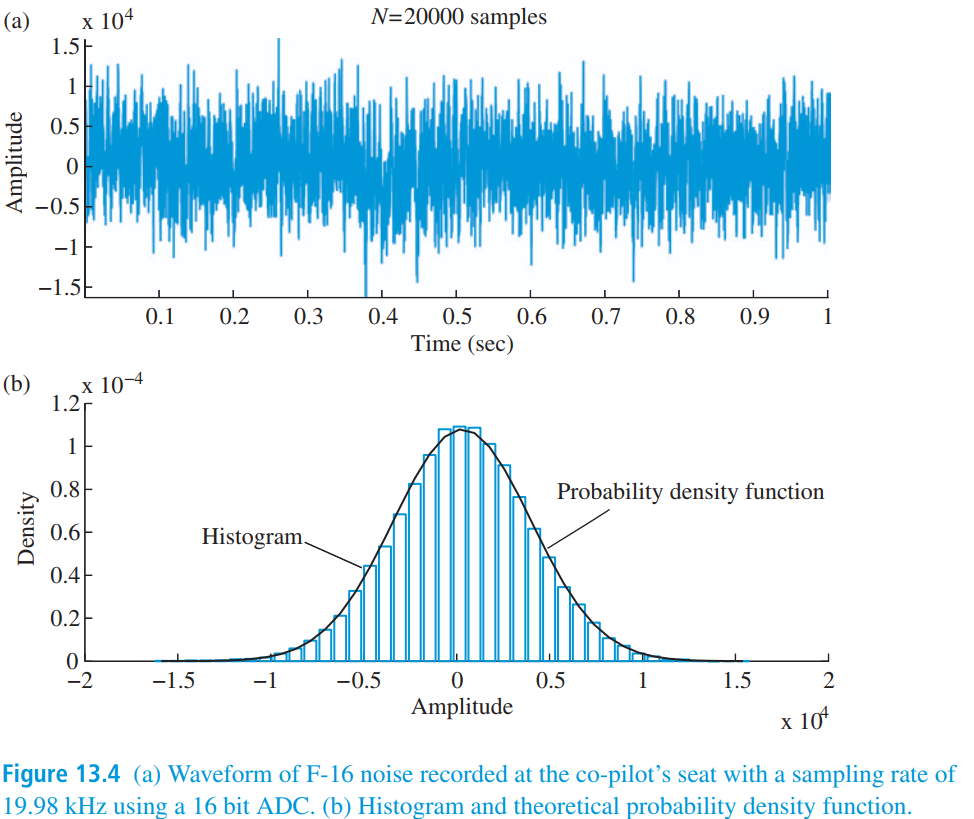

To generate $N$ random numbers for a Gaussian random variable $X$ with mean $m$ and variance $\sigma^2$ we use following MATLAB functions

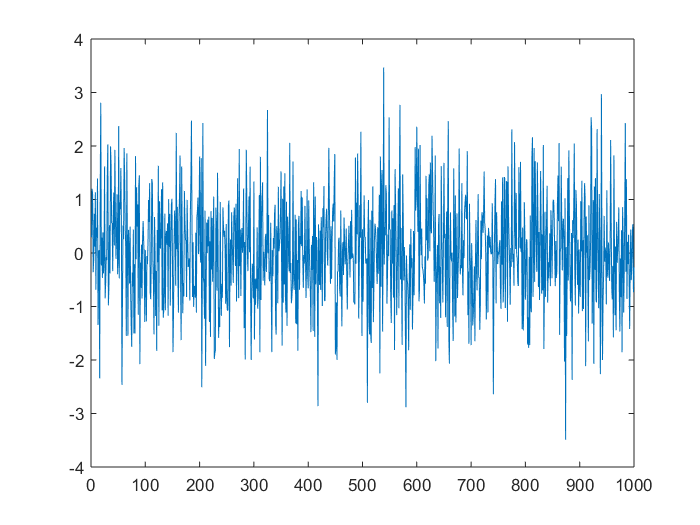

N = 1000;
sigma = 1; 
m = 0;
x = sigma*randn(N,1)+m;
plot(x);

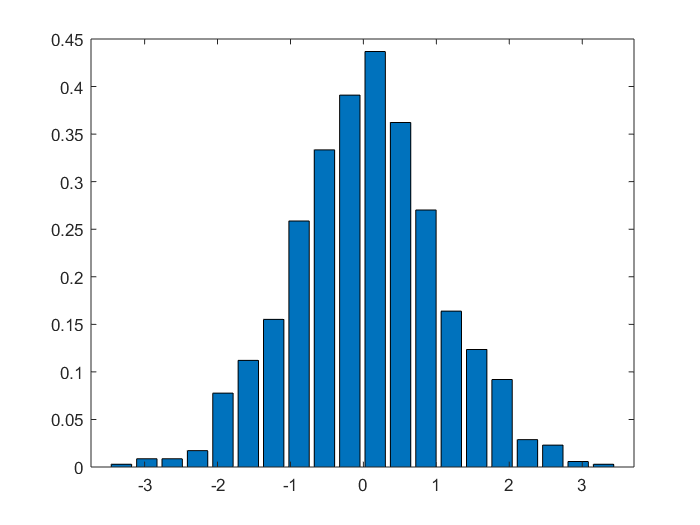

[xo, px] = epdf(x, 20);
bar(xo, px)

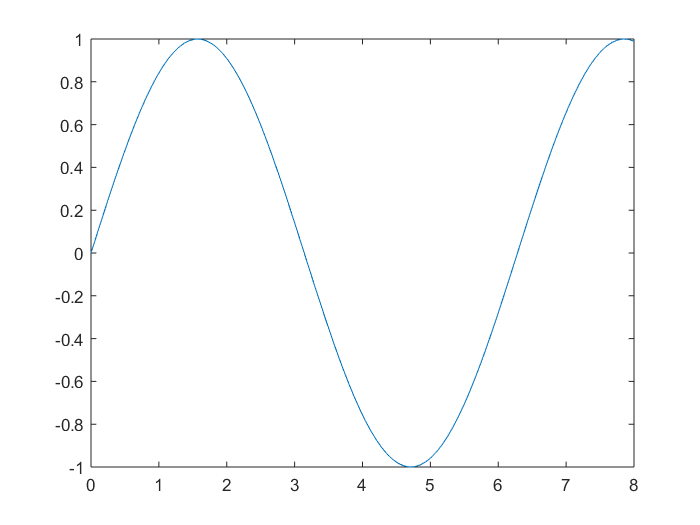

n = linspace(0, 8, 100);
y = sin(n);
plot(n, y);

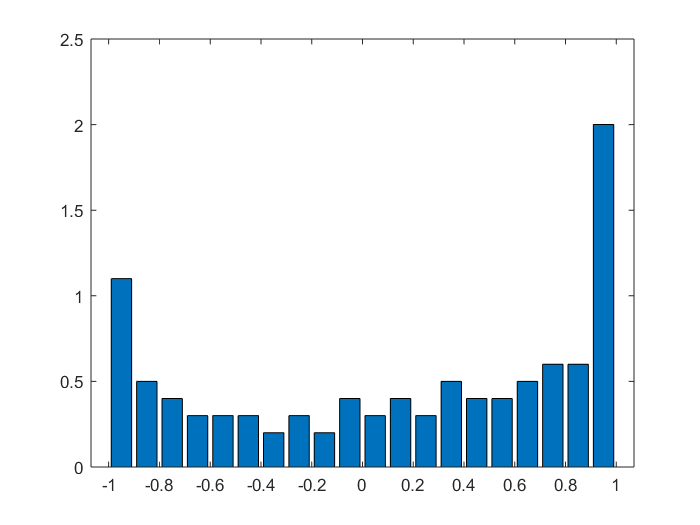

[xo, px] = epdf(y, 20);
bar(xo, px);

A probability distribution of a continuous random variable $X$ denoted $f_X \left(x\right)$ is called the ***probability density function*** (PDF). **Note!** that the function $f_X \left(x\right)$ does not represent the probability of any event. It is only when the function is integrated between two points that it yields a probability. 

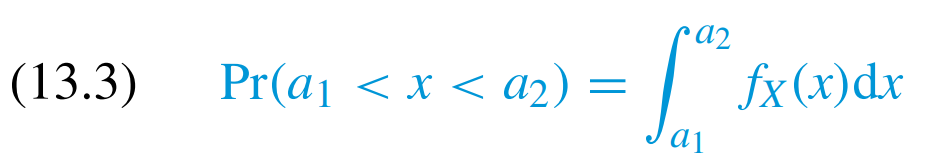

The*** cumulative distribution function*** (CDF) of a random variable $X$, denoted $F_X \left(a\right)$is the area under the curve $f_X \left(x\right)$ from $-\infty$ to $a$:

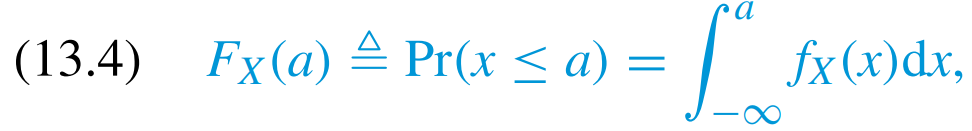

Since the $f_X \left(x\right)>0$, the CDF is monotonically increasing from $F_X \left(-\infty \right)=0$ to $F_X \left(\infty \right)=1$

### Statistical averages

The ***mean value*** or ***expectation*** of a random variable $X$ is defined as:

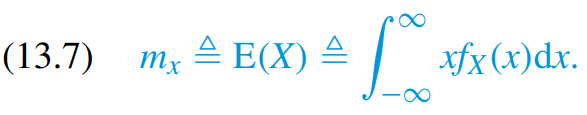

The mean value is an average of the values that a random variable takes on, where each value is weighted by the probability that the random variable is equal to that value.

The mean value is a measure of where the values of the random variable $X$ are centered.

#### Expection rules

Let $X$ and $Y$ be two random variables and $a$ and $b$ be two constants. Following expectation properties apply:

- $E\left\lbrack a\right\rbrack =a$               e.g. $E\left(42\right)=42$

- $E\left\lbrack a\;X\right\rbrack =a\;E\left\lbrack X\right\rbrack$   e.g. if you multiply every value by 2, the expectation doubles

- $E\left\lbrack a\pm X\right\rbrack =a\pm E\left\lbrack X\right\rbrack$ e.g. if you add 42 to every case, the expectation increases by 42

- 
$$E\left\lbrack X+Y\right\rbrack =E\left\lbrack X\right\rbrack +E\left\lbrack Y\right\rbrack$$


- If $X$ and $Y$ are independent, then $E\left\lbrack \mathrm{XY}\right\rbrack =E\left\lbrack X\right\rbrack E\left\lbrack Y\right\rbrack$

- 
$$E\left\lbrack a\pm \mathrm{bX}\right\rbrack =a\pm E\left\lbrack b\;X\right\rbrack =a\pm b\;E\left\lbrack X\right\rbrack$$


- 
$$E\left\lbrack b\left(a\pm \textrm{X}\right)\right\rbrack =b\;E\left\lbrack a\pm \textrm{X}\right\rbrack =b\left(a\pm E\left\lbrack X\right\rbrack \right)$$


- $E\left\lbrack a\;X+b\;Y\right\rbrack =a\;E\left\lbrack X\right\rbrack +b\;E\left\lbrack Y\right\rbrack$ (using rule 2 and 4)

The ***variance*** of a random variable $X$ is defined as:

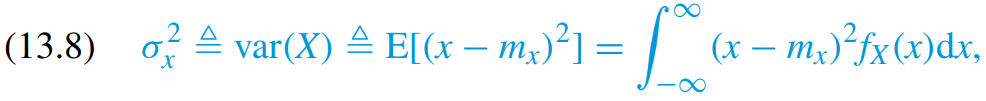

Another way to compute the variance is:

(13.11)     $\mathrm{var}\left(X\right)=E\left\lbrack X^2 \right\rbrack -{\left(E\left\lbrack X\right\rbrack \right)}^2 =E\left\lbrack X^2 \right\rbrack -m_x^2$

The variance measures the spread of the distribution about its mean value.

A small variance indicates that $X$ is more likely to assume values close to its mean.

A large variance indicates that the values of *X *are spread over a wider interval about the mean.

The variance is used as a measure of variability of a random variable.

#### Variance Rules

Let $X$ and $Y$ be two random variables and $a$ and $b$ be two constants. Following variance identities apply:

- 
$$\mathrm{var}\left(a\right)=0$$


- 
$$\textrm{var}\left(a\pm X\right)=\mathrm{var}\left(X\right)$$


- 
$$\textrm{var}\left(b\;X\right)=b^2 \cdot \textrm{var}\left(X\right)$$


- 
$$\textrm{var}\left(a\pm b\;X\right)=b^2 \cdot \mathrm{var}\left(X\right)$$


- If $X$ and $Y$ are indepedent i.e. $\mathrm{cov}\left(X,Y\right)=0$ then $\mathrm{var}\left(X\pm Y\right)=\mathrm{var}\left(X\right)+\mathrm{var}\left(Y\right)$

- If $X$ and $Y$ are indepedent $\mathrm{var}\left(a\;X+b\;Y\right)=a^2 \;\mathrm{var}\left(X\right)+b^2 \;\mathrm{var}\left(Y\right)$

The ***standard deviation*** is a measure of spread which has the same units as the original observations:

We only use the subscript for the mean, variance and standard deviation when different random variables are compared.

### Useful Distributions

#### Uniform distribution

A random variable $X$ uniformly distributed over the interval $\left(a,b\right)$ is denoted by $X\sim U\left(a,b\right)$. 

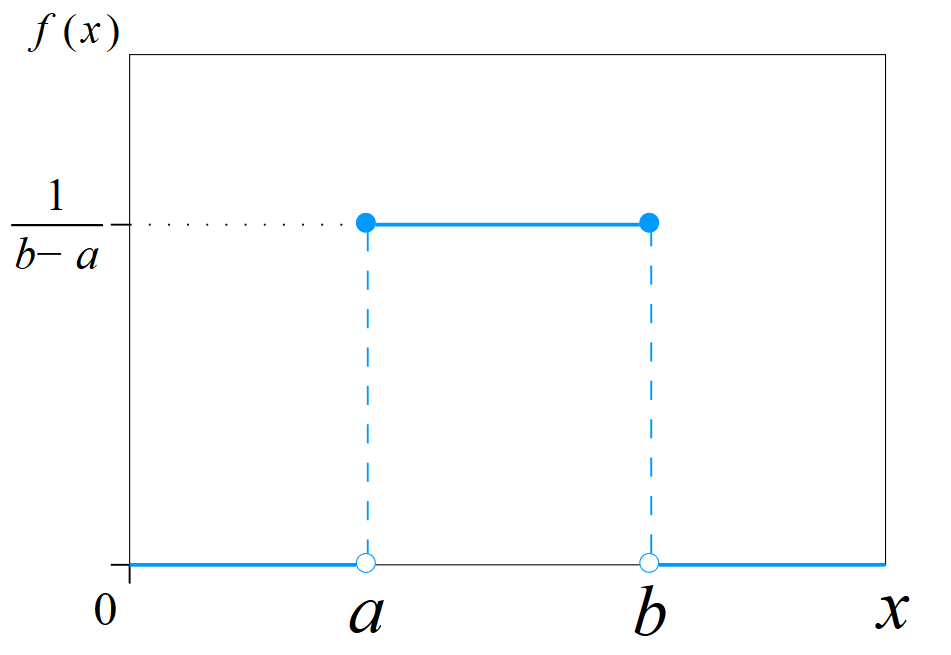

The probability density function is given by:

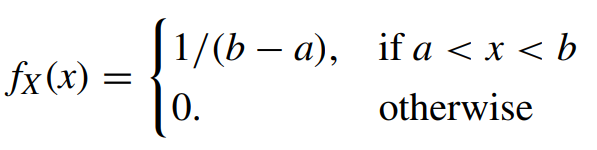

The mean is


$$E\left(X\right)=\frac{b+a}{2}$$


The mean of squared is:


$$E\left(X^2 \right)=\frac{a^2 +b^2 +\mathrm{ab}}{3}$$


The variance is:


$$\mathrm{var}\left(X\right)=E\left(X^2 \right)-{\left\lbrack E\left(X\right)\right\rbrack }^2 =\frac{1}{12}{\left(b-a\right)}^2$$


The MATLAB function **rand **generates random numbers according to $X\sim U\left(0,1\right)$

### Normal distribution

A random variable $X$ normally distributed with mean $m$ and variance $\sigma^2$ is denoted $X\sim N\left(m,\sigma^2 \right)$. 

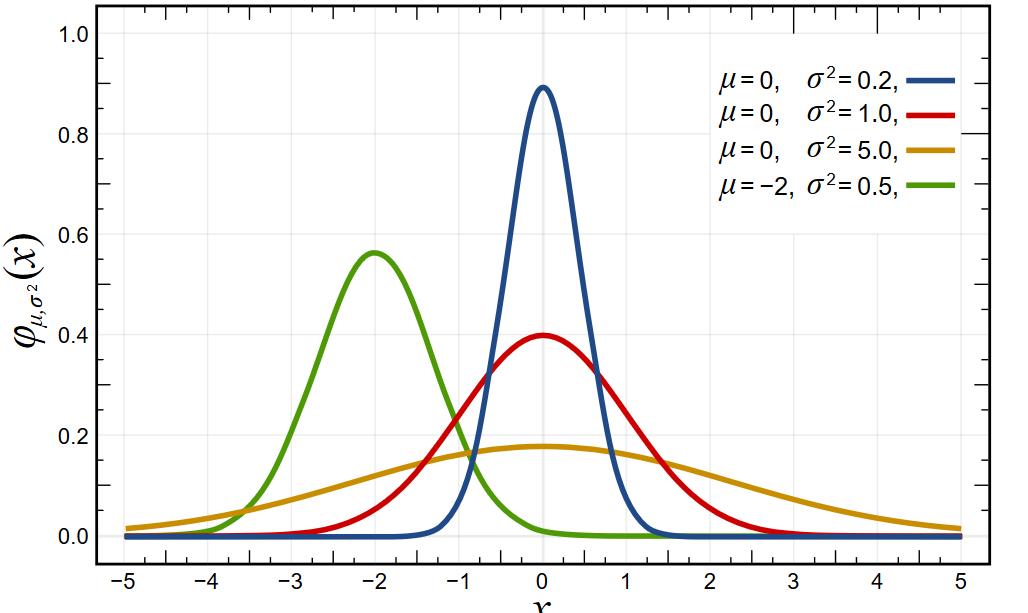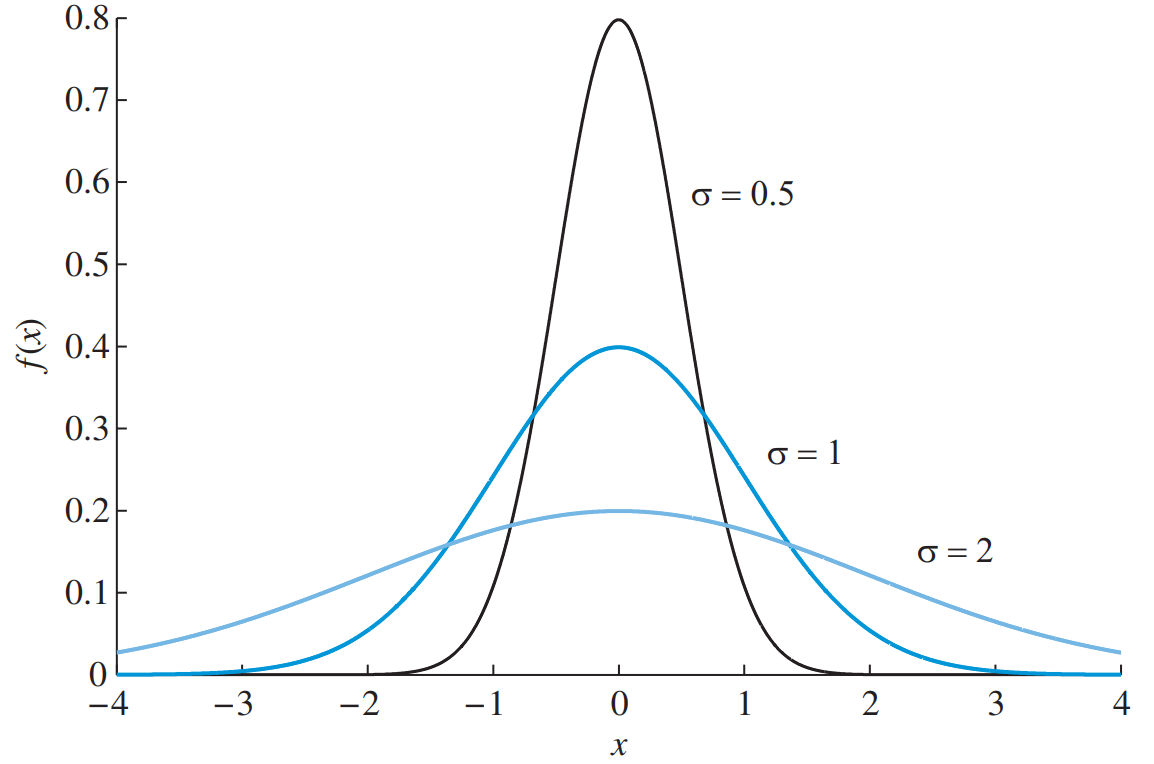

The probability density function of a normal distribution for various values of the standard deviation. The spread of the distribution increases with increasing $\sigma$; the height is reduced because the area is always equal to unity.

Its probability density function is given by:

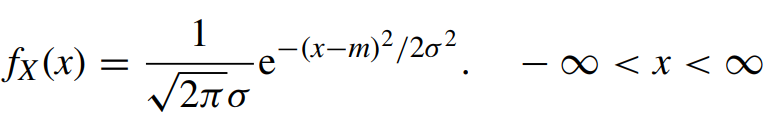

The mean is 


$$E\left(x\right)=m$$


The variance is:


$$E\left(X\right)=\sigma^2$$


#### Properties of normal random variables

Any linear combination of normal random variables is itself a normal random variable.  

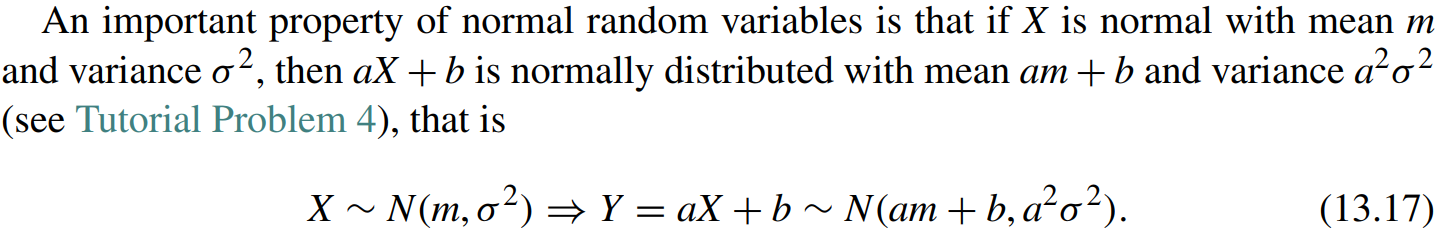

Central Limit Theorem: the sum of a large number of independent random variables has approximately a normal distribution. 

## **Jointly distributed random variables**  

### Convariance

**Covariance** provides a measure of the association between two random variables $X$ and $Y$. The covariance can be used to summarise the information provided by the following scatter plot:

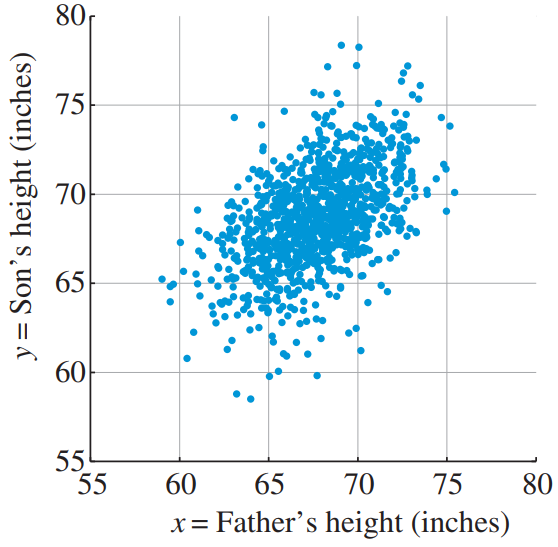

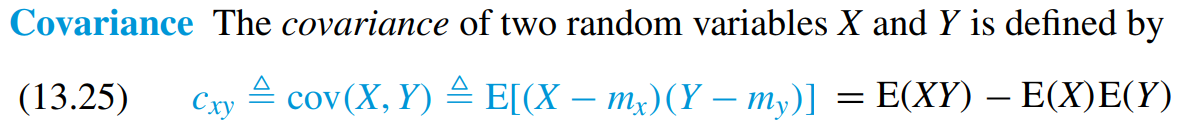

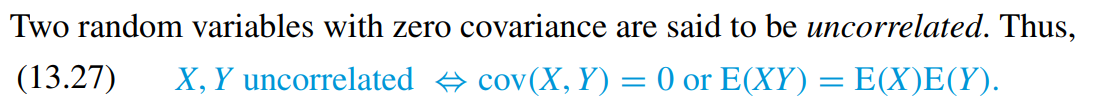

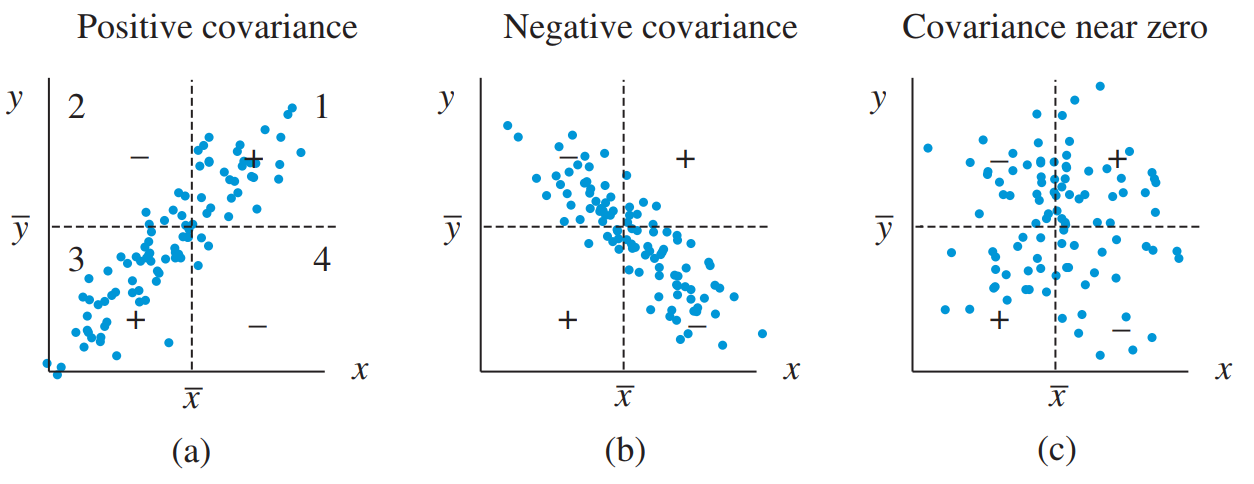

a) The relationship between *X *and *Y *is positive means that as *X *increases so does *Y*

b) The relationship between *X *and *Y *is negative meaning that as *X *increases, *Y *will decrease.

c) The random variables$X$ and $Y$ are not related i.e. uncorrelated.

### Correlation

The correlation between two random variables $X$ and $Y$ is defined as:


$$r_{\mathrm{xy}} =E\left\lbrack \mathrm{XY}\right\rbrack$$


Correlation and covarance may create some confusion. Zero correlation implies that $X$ and $Y$ are orthogonal whereas zero covariance implies that $X$ and $Y$ are uncorrelated.

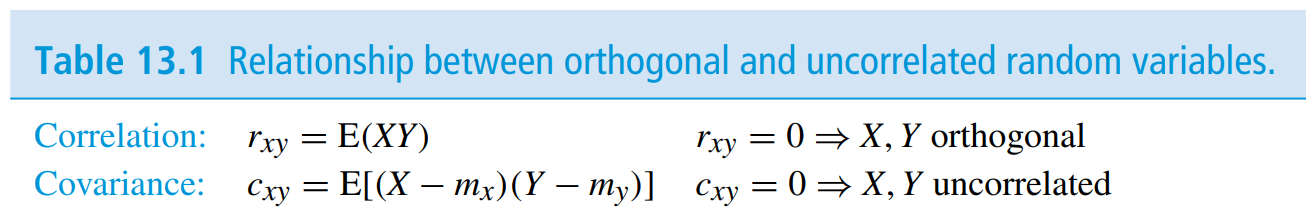

## Linear estimation

# Functions

function [xo, px]=epdf(x, bins)
    [nx,xo]=hist(x,bins);
    dx=xo(3)-xo(2);
    px=nx/(dx*length(x));
end